## 1

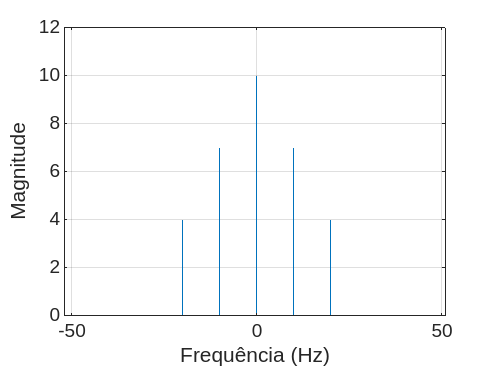

Fa = 100;
t = 0:1/Fa : 1-1/Fa;
x = 10 + 14*cos(20*pi*t - pi/3) + 8*cos (40*pi*t + pi/2);
% xt = 10 + 7 * exp(1i*pi*-20+1i*pi/3 * t)+ 7 * exp(1i*pi*20-1i*pi/3 * t) + 4 * exp(1i*pi*40-1i*pi/2 * t) + 4 * exp(1i*pi*-40+1i*pi/2 * t);
Espetro(x,1/Fa);

## 2

function [X,f] = Espetro(x,Ta)   
    fa = 1/Ta;
    N = length(x);
    X=fftshift(fft(x))/N;

    f = (0:N-1) * fa/N - fa/2;

    h = stem(f, abs(X));
    set(h, 'Marker', 'none')
    xlabel("Frequência (Hz)")
    ylabel("Magnitude")
    grid;
end


## 3

## a)

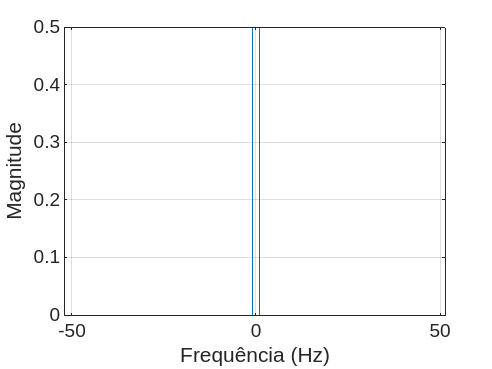

Fa = 100;
t = 0:1/Fa : 2-1/Fa;
xt = sin(2*pi*t);
Espetro(xt,1/Fa);

## b)

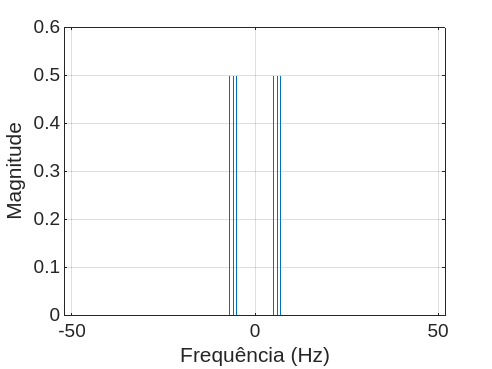

Fa = 100;
t = 0:1/Fa : 50-1/Fa;
xt = sin(10*pi*t) + cos(12*pi*t) + cos(14*pi*t - pi/4);
Espetro(xt,1/Fa);

## c)

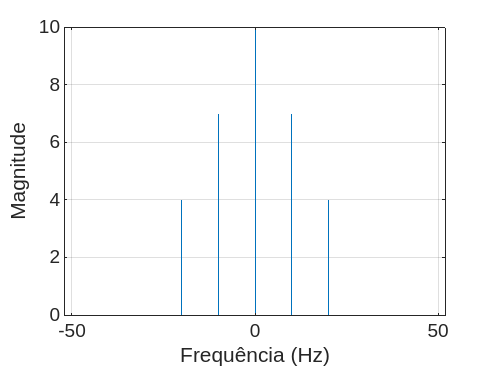

Fa = 100;
t = 0:1/Fa : 100-1/Fa;
xt = 10 + 14*cos(20*pi*t - pi/3) + 8*cos (40*pi*t + pi/2);
Espetro(xt,1/Fa);

## d)

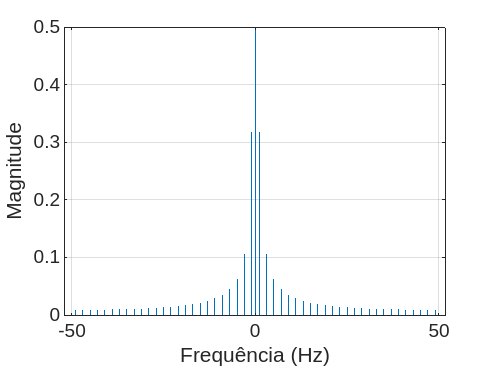

Fa = 100;
t = 0:1/Fa : 5-1/Fa;
xt = 0.5*square(2*pi*t) + 0.5;
Espetro(xt,1/Fa);

## e)

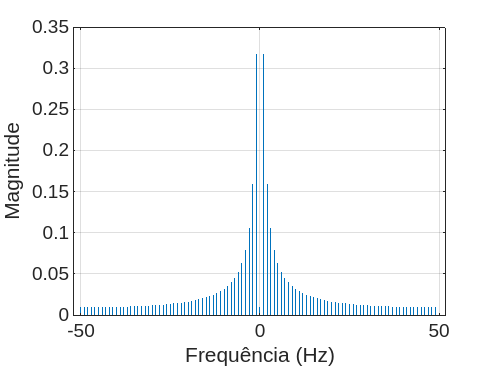

Fa = 100;
t = 0:1/Fa : 5-1/Fa;
xt = sawtooth(2*pi*t);
Espetro(xt,1/Fa);

## 4.

function [x,t] = Reconstroi(X,f)
    N = length(X);
    x = ifft(ifftshift(X))*N;
 
    fa = max(f)*2;
    Ta = 1/fa;
    t = (0:N-1)*Ta;

    plot(t,abs(x));
    xlabel("Tempo (s)");
    ylabel("Amplitude");
    title("Sinal")
    grid;
end

## TESTES

Fa = 100; 
t = 0:1/Fa : 2-1/Fa;
x = sin(2*pi*t);
[X,f] = Espetro(x,1/Fa);

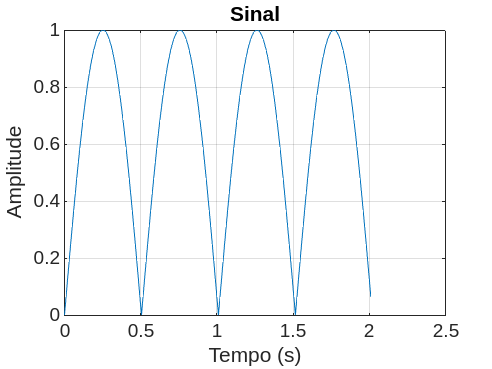

Reconstroi(X,f);

Fa = 100; 
t = 0:1/Fa : 50-1/Fa;
x = sin(10*pi*t)+cos(12*pi*t)+cos(14*pi*t-pi/4);
[X,f] = Espetro(x,1/Fa);

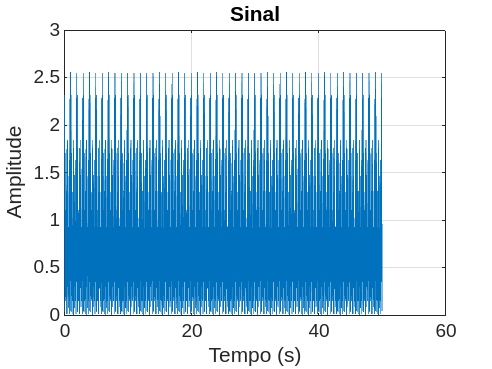

Reconstroi(X,f);